clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

%%globale Variablen des Rotors
R=50;           %%Rotorradius [m]
lamda_A=7;      %%Schnelllaufzahl   [1]
z=3;            %%Blattanzahl       [1}

%%lokale Variablen zum einfgügen der Profile
name='NACA0012';    %%Profilname gerade nur NACA 4-digit profile
%%alpha_A=6;          %%Anstellwinkel     [°]
t=0.25;             %%Position Blattachse
r=40;               %%Position des Profils auf dem Blatt

edit=1;             %%edit an oder aus

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof(1)=profile_transform(R,r,name,lamda_A,z, t);
   else
       if check_existing(prof,r) == 0
            l=length(prof);
            prof(l+1)=profile_transform(R,r,name,lamda_A,z, t);
            prof=bld_sort(prof);
       else
           disp('Profil an dieser Blattposition existiert bereits. Anderen Profilposition waehlen!')
       end
   end
end

existing = logical
   0


alpha_A = 16

deep_bld = 1.0498

profile =     0.7773    0.7710    0.7599    0.7469    0.7324    0.7168    0.7005    0.6839    0.6671    0.6502    0.6332    0.6162    0.5992    0.5822    0.5651    0.5481    0.5310    0.5139    0.4968    0.4797    0.4626    0.4455    0.4284    0.4113    0.3942    0.3771    0.3600    0.3429    0.3258    0.3087    0.2916    0.2746    0.2575    0.2405    0.2234    0.2064    0.1894    0.1724    0.1555    0.1385    0.1216    0.1048    0.0879    0.0711    0.0544    0.0377    0.0210    0.0045   -0.0120   -0.0284
   -0.1253   -0.1233   -0.1199   -0.1159   -0.1115   -0.1068   -0.1019   -0.0970   -0.0921   -0.0872   -0.0823   -0.0774   -0.0726   -0.0678   -0.0631   -0.0584   -0.0537   -0.0491   -0.0445   -0.0399   -0.0354   -0.0309   -0.0265   -0.0221   -0.0178   -0.0135   -0.0092   -0.0050   -0.0009    0.0032    0.0072    0.0112    0.0150    0.0189    0.0226    0.0263    0.0299    0.0334    0.0368    0.0401    0.0433    0.0464    0.0494    0.0522    0.0550    0.0576    0.0600    0.0623    0.064

## plot

l = 9

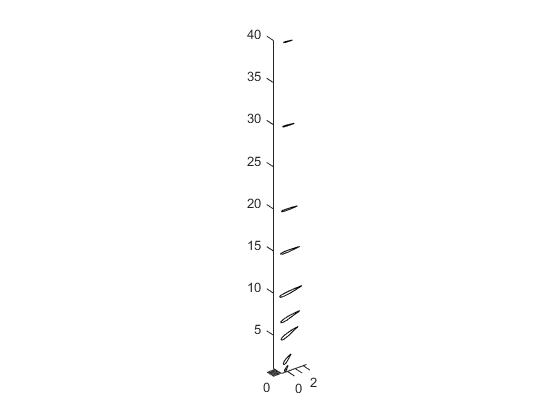

bld_plot(prof)